# Share Multiple Fields of Data Between MATLAB and JavaScript

Create an HTML UI component that displays data with multiple fields.

Create an item card component that lists an item name, price, and quantity. Design the HTML UI component to take in the item data as a `struct` in MATLAB. First, check how `struct` data is encoded when the data is transferred from MATLAB to JavaScript by using the `jsonencode` function.

matlabData = struct("ItemName","Apple","Price",2,"Quantity",10);
jsonencode(matlabData)

For more information about how HTML components transfer data between MATLAB and JavaScript, see [Create and Debug HTML Content in Apps](docid:creating_guis#mw_91d32db7-b12c-47e3-893d-502c2f8b0c98).

Next, create an HTML source file called `itemCard.html` that creates and styles the item card HTML component. In the file:

- Use a `<style>` tag to define internal CSS styles for an item card.

- Write a `setup` function inside of a `<script>` tag to detect when the `Data` property of the MATLAB HTML UI component object changes, and then access the `Data` property of the JavaScript `htmlComponent` object. The data is encoded as a JavaScript object with multiple properties. Access these properties to update the content of the HTML component.

- Use a `<body>` tag to create the main HTML document content.

Create an HTML component in a UI figure. Specify `itemCard.html` as the HTML source and an item data `struct` as the component data.

itemData = struct("ItemName","Apple","Price",2,"Quantity",10);
fig = uifigure;
c = uihtml(fig,"HTMLSource","itemCard.html","Data",itemData);

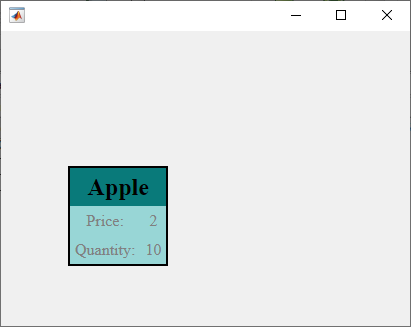

*Copyright 2022 The MathWorks, Inc.*